# Relay Feedback Control

Open serial to Pico data port

clear s % closes ports already open
s = serialport('COM4',9600) % Check COM#

s =   Serialport with properties:

                 Port: "COM4"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


Calculate linear fit parameters to find base voltages

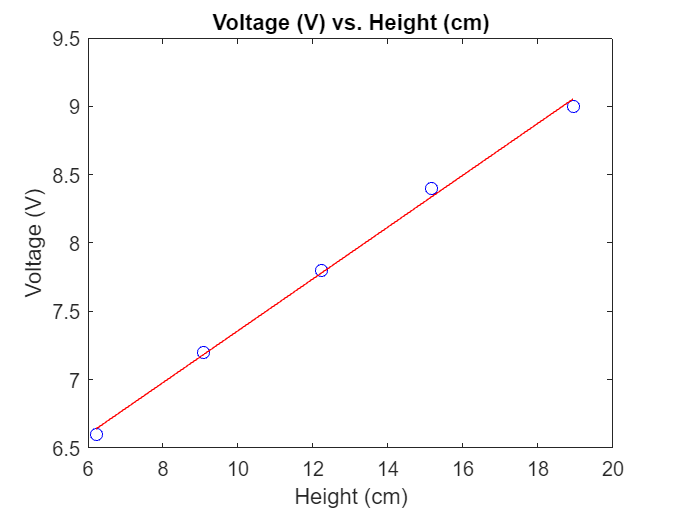

duty_cycle = [55 60 65 70 75]; % expiremented duty cycles
height = [6.22 9.09 12.24 15.15 18.95];
%hole_num = [3.5 5 6.5 7.5 9.5 11 12]; % resultant hold number

voltage = (duty_cycle ./ 100) .* 12; % convert duty_cycle to fan voltage
%height = hole_num .* 2; % convert hole_num to ball height

plot(height, voltage, 'bo') % plot data points

pfit = polyfit(height,voltage,1); % fit line to data 
pval = polyval(pfit, height); % evaluate fitted line

hold on
plot(height, pval, 'r') % plot fitted line
hold off

title("Voltage (V) vs. Height (cm)")
xlabel("Height (cm)")
ylabel("Voltage (V)")


% extract parameters
a = pfit(1)

a =    0.189851688407121


b = pfit(2)

b =    5.459128681940197


Send request for number of samples to Pico and begin live plotting

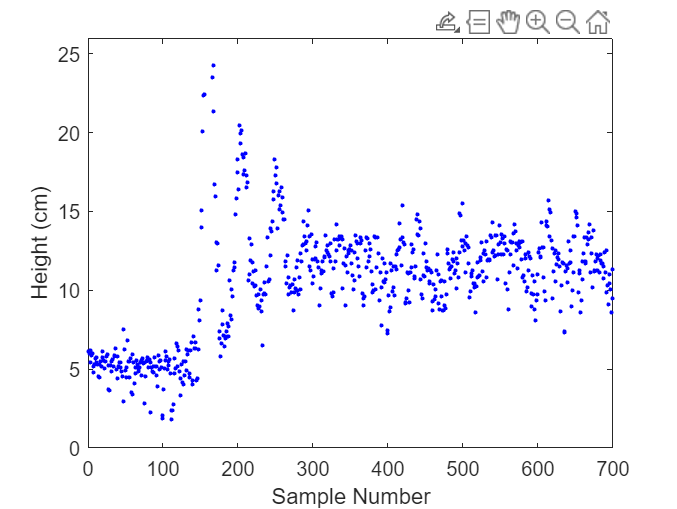

desired_height = 10; 
s.writeline(num2str(desired_height)) % send desired height to Pico

samples = 700;
s.writeline(num2str(samples)) % send number of samples to Pico

data = zeros(1, samples); % create emply row vector for data collection

% loop for every sample
for i = 1:samples   
    data(i) = s.readline(); % receive distance from serial
    plot(i,data(i),'b.') % plot data

    xlabel("Sample Number")
    ylabel("Height (cm)") 
    axis([0 samples 0 26]) % x and y axis limits
    hold on
end
hold off